# Aula 8 - Laboratório de Controle - 2021/1

## Projeto do controlador PID via LR

## Nome: Yuri Rissi Negri

[Video sobre este live script](https://youtu.be/QTGdJ07Edbw)

turma=5 ;
I=8 ;
Tempo=4;

M=[5 9 3 4 1 2 12 7 11 10 8 6
     2 4 5 11 10 1 9 8 7 3 6 12
     9 1 12 8 5 11 6 3 2 4 10 7
     7 6 9 2 11 5 8 4 3 10 12 1
    12 9 3 11 7 8 5 2 10 1 6 4]';

wn=M(I,turma);


arquivo='motor_cc_R2018.slx';  % Apague a linha que não usar


load dados.mat
i=wn*50;
ind=(i-20):(i+35);
y1=y1(ind);
u1=u1(ind);
t1=t1(ind);
Ref=mean(y1(end-10:end));
u0=mean(u1(1:10));


## Atividade 0 - Obtenção do modelo

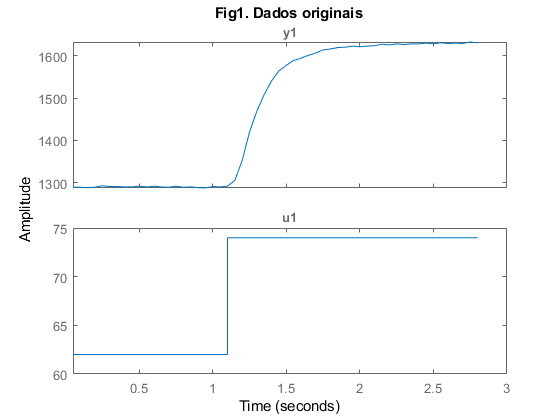

dat=iddata(y1,u1,Ts);
dat_1=iddata(y1-y1(1),u1-u1(1),Ts);
figure
plot(dat);title('Fig1. Dados originais');

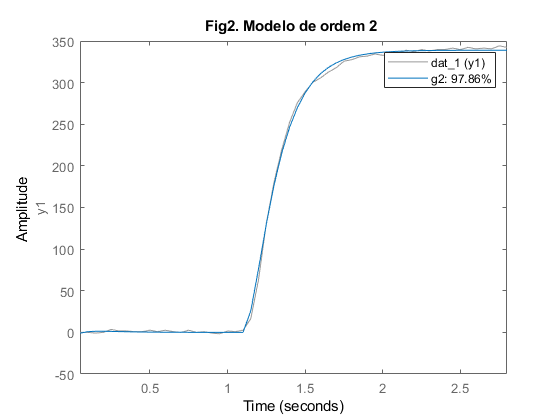

g2=tfest(dat_1,2,0);
g2=tf(g2.Numerator,g2.Denominator);
K=freqresp(g2,0);
figure
compare(dat_1,g2);title('Fig2. Modelo de ordem 2 ');

s=stepinfo(g2);
ts_ma=s.SettlingTime

ts_ma = 0.7316

N=100;
Ts=0.01;

## Atividade 1 - Projeto do controlador PI via LR e simulação com g2

1.1 Use o LR para projetar o controlador PI para g2 de modo a atender $UP<5\%$e o menor tempo de estabelecimento possível, necessariamente menor que o de malha aberta (ts_ma). Gere 5 controladores PI C1...C5 para 5 localizações do zero Ki/Kp, como explicado no video, ajustando Kp para o menor tempo de estabelecimento.

    Nessa parte do projeto, selecionamos os melhores candidatos de zero para o PI e de ganho que respeitasse $UP<5\%$ com base na nossa g2. Contudo, temos que levar em consideração que g2 é uma aproximação do nosso sistema real, então esses valores estão sujeitos a mudanças e são apenas uma base para o início da nossa análise. 

figure
desenhalr(C1,g2,ts_ma); % C1 projetado no rltool e exportado para o workspace

Undefined function or variable 'C1'.

m1=feedback(C1*g2,1);
s=stepinfo(m1);
upc=[s.Overshoot];
tsc=[s.SettlingTime];

figure
desenhalr(C2,g2,ts_ma);
m2=feedback(C2*g2,1);
s=stepinfo(m2);
upc=[upc s.Overshoot];
tsc=[tsc s.SettlingTime];

figure
desenhalr(C3,g2,ts_ma);
m3=feedback(C3*g2,1);
s=stepinfo(m3);
upc=[upc s.Overshoot];
tsc=[tsc s.SettlingTime];

figure
desenhalr(C4,g2,ts_ma);
m4=feedback(C4*g2,1);
s=stepinfo(m4);
upc=[upc s.Overshoot];
tsc=[tsc s.SettlingTime];


figure;
desenhalr(C5,g2,ts_ma);
m5=feedback(C5*g2,1);
s=stepinfo(m5);
upc=[upc s.Overshoot];
tsc=[tsc s.SettlingTime];

figure
step(m1,m2,m3,m4,m5);legend('m1','m2','m3','m4','m5');
title('Resposta para os controladores PI');

figure
subplot(2,1,1);bar(upc);title('UP') 
subplot(2,1,2);bar(tsc);title('Tempo estabelecimento'); 


## Atividade 2 - Teste do controlador PI no motor

2.1 Teste os controladores PI no motor, de modo a atender as especificações (UP<5% e ts de MF < ts de MA). Escolha o que melhor atender, e compare os resultados do teste no motor com os da atividade 1. Considere rever o projeto, caso os resultados não atendam as especificações.

    Ao aplicarmos os controladores sintetizados para g2 em nosso sistema real, percebemos que não foram gerados resultados satisfatórios. Dessa forma, observando as respostas no sistema real, foi feito um ajuste para a obtenção dos melhores resultados possíveis variando a posição do zero e ganho, porém se mantendo naquela faixa de valores definidas inicialmente por g2. Assim, pudemos perceber que o resultado que nos gerou uma resposta com menor ts e UP<5 em nossa planta real, foi o controlador C5, que se observado no gráfico de barras da atividade 1, foi o controlador que teve um maior tempo de estabelecimento em g2 entre os cinco controladores, mostrando que os parâmetros definidos na análise de g2 são apenas valores de base para que seja feita a análise do sistema real.

C=C5;

[kp,ki,kd]=piddata(C);
kp = kp*1;

[Y,t]=simula_slx(arquivo,Tempo);
[~,UP,SettlingTime] = desempenho(Y(:,[2,3]),t,Ref,2);
str = sprintf('Controlador PI: ts(ma) = %.1f ts(mf) = %.3f  UP = %.1f ',ts_ma, SettlingTime,UP);
figure
t1=sum(t<2)+1;
subplot(2,1,1);plot(t(t1:end)-2,Y(t1:end,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');title(str);
subplot(2,1,2);plot(t(t1:end)-2,Y(t1:end,2));title('Sinal de controle PWM');

2.2 Compare o projeto via LR e via método lambda, considerando a flexibilidade e complexidade de projeto por eles oferecida.

    Em geral, conseguimos obter melhores resultados com o projeto via RL. A flexibilidade e liberdade que o método LR nos fornece em comparação ao método lamba, nos permite escolher os parâmetros que irão gerar o melhor controlador para aquele o sistema especifico, ao contrário do método lambda que é um método mais geral.

    Dessa forma, podemos sintetizar o controlador para atingir os nossos critérios de projeto, de forma mais eficiente, adaptando os valores de ganho conforme a necessidade do projeto. Por exemplo para o nosso sistema, fomos capazes de varias os valores do ganho e da posição do zero com o objetivo de se obter o menor valor de tempo de estabelecimento possível, enquanto no método lambda estávamos limitados aos valores de ts fornecidos pela escolha do lambda.     

## Atividade 3 - Projeto do controlador PID via LR

3.1 Seja C o controlador PI selecionado na atividade 2.1. Adicione ao projeto o zero do ganho derivativo, gere o controlador C6, e veja as melhorias que consegue nos resultados, simulando o controlador no motor. Como escolheu a localização do zero?

    Fixando o zero encontrado no controlador PI, primeiro utilizando a ferramenta sisotool, fixamos um valor de sobressinal em nossas buscas para que pudesse se comparar os ganhos e tempos de estabelecimento para diferentes valores de zero no PD. Assim, atendendo nosso critério de projeto, encontramos o melhor zero para o PD do nosso sistema aproximado g2, com o menor tempo de estabelecimento. Com isso, aplicamos o controlador a nossa planta real e pudemos observar que poderíamos obter melhores resultados. Dos resultados de g2, obtivemos assim uma base para a busca do melhor zero e ganho para nossa planta real. 

    Assim, com esse intervalo de valores como base, foi sei variando o valor de ganho e local do zero e aplicando a planta real a fim de se obter melhores resultados. Portanto, quando foi encontrado um resultado satisfatório, foi feito o ajuste fino, sempre observando a resposta real do sistema. 

figure;
desenhalr(C6,g2,ts_ma);
[kp,ki,kd]=piddata(C6);
[Y,t]=simula_slx(arquivo,Tempo);
[erro,UP,SettlingTime] = desempenho(Y(:,[2,3]),t,Ref,2);
str = sprintf('Controlador PID: ts(ma) = %.1f ts(mf) = %.3f  UP = %.1f ',ts_ma, SettlingTime,UP);
figure
t1=sum(t<2)+1;
subplot(2,1,1);plot(t(t1:end)-2,Y(t1:end,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');title(str);
subplot(2,1,2);plot(t(t1:end)-2,Y(t1:end,2));title('Sinal de controle PWM');


datetime('now')
pwd